% timeseries에서 시간 데이터 추출 후 변환
timeData = out.loadcellandpos.Time;
LoadcellData = out.loadcellandpos.Data(:,1);
DisplacementData = out.loadcellandpos.Data(:,2);
TactilesensorData = out.loadcellandpos.Data(:,3);
timeVector = seconds(timeData);  % 초 단위로 변환

% timetable 생성
data1 = timetable(timeVector, LoadcellData, 'VariableNames', {'LoadcellData'});
data2 = timetable(timeVector, DisplacementData, 'VariableNames', {'DisplacementData'});
data3 = timetable(timeVector, TactilesensorData, 'VariableNames', {'TactilesensorData'});

% 1587행부터 3167행까지의 데이터만 선택
% data1 = data1(1587:3167,:);
% data2 = data2(1587:3167,:);

% Force 계산 (LoadcellData * -5)
Initial_force= mean(data1.LoadcellData(1:50));
Force = (data1.LoadcellData-Initial_force) * -5;

Initial_Displacement = mean(data2.DisplacementData(1:50));
Displacement =(data2.DisplacementData-Initial_Displacement)*-2;

Initial_Sensor = mean(data3.TactilesensorData(1:50));
Sensor = data3.TactilesensorData;


% Force threshold 필터링
% Force_threshold_upper = 5.0;
% Force_threshold_lower = 0.05;
% valid_indices1 = Force >= Force_threshold_lower;
% valid_indices2 = Force <= Force_threshold_upper;
% valid_indices = valid_indices1 & valid_indices2;

Sensor_threshold_upper = 2110;
Sensor_threshold_lower = Initial_Sensor;
valid_indices1 = Sensor >= Sensor_threshold_lower;
valid_indices2 = Sensor <= Sensor_threshold_upper;
valid_indices = valid_indices1 & valid_indices2;



% 필터링된 데이터만 사용
 Force_filtered = Force(valid_indices);
 Displacement_filtered = Displacement(valid_indices);
 Sensor_filtered = Sensor(valid_indices);
 timeVector_filtered = data1.timeVector(valid_indices);



% fprintf('전체 데이터 포인트: %d개\n', length(Force));
% fprintf('Force >= %.3f 인 데이터 포인트: %d개\n', Force_threshold_upper, length(Force_filtered));
% fprintf('데이터 사용률: %.1f%%\n', (length(Force_filtered)/length(Force))*100);

% Force vs Sensor 그래프 그리기 (필터링된 데이터만 사용)
figure;
plot(Sensor_filtered, Force_filtered, 'b-', 'LineWidth', 1.5);
xlabel('Sensor (value)');
ylabel('Force (N)');
title(sprintf('Force vs SensorData'));
grid on;

% 선형 피팅을 통한 stiffness 계산 (필터링된 데이터만 사용)
p = polyfit(Sensor_filtered, Force_filtered, 1)  % 1차 다항식 피팅

p =     0.0003   -0.3589


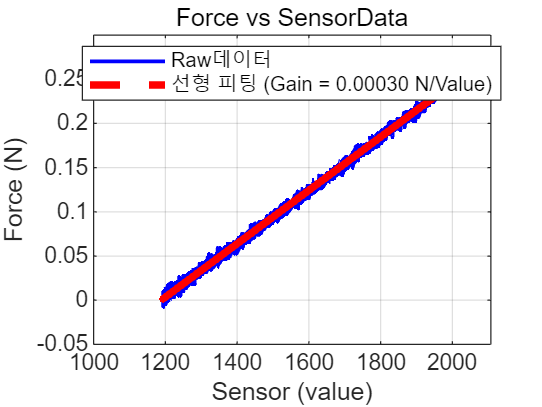

stiffness = p(1);  % 기울기가 stiffness

% 피팅된 직선 추가
hold on;
fitted_force = polyval(p, Sensor_filtered);
plot(Sensor_filtered, fitted_force, 'r--', 'LineWidth', 3);
legend('Raw데이터', sprintf('선형 피팅 (Gain = %.5f N/Value)', stiffness), 'Location', 'best');


% 결과 출력
fprintf('계산된 Gain: %.5f N/mm\n', stiffness);

계산된 Gain: 0.00030 N/mm


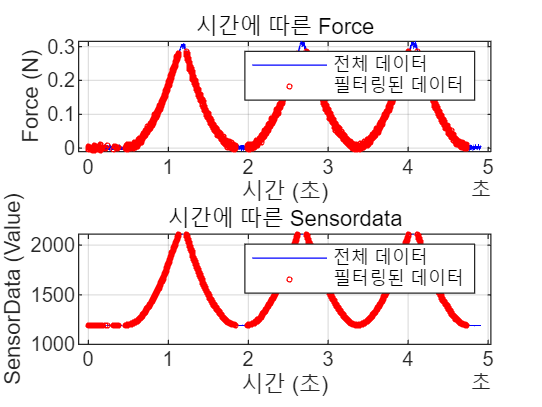


% 추가 분석 그래프
figure;
subplot(2,1,1);
plot(data1.timeVector, Force, 'b-', 'DisplayName', '전체 데이터');
hold on;
plot(timeVector_filtered, Force_filtered, 'ro', 'MarkerSize', 2, 'DisplayName', '필터링된 데이터');
xlabel('시간 (초)'); ylabel('Force (N)'); title('시간에 따른 Force'); 
legend('show'); grid on;

subplot(2,1,2);
plot(data3.timeVector, Sensor, 'b-', 'DisplayName', '전체 데이터');
hold on;
plot(timeVector_filtered, Sensor_filtered, 'ro', 'MarkerSize', 2, 'DisplayName', '필터링된 데이터');
xlabel('시간 (초)'); ylabel('SensorData (Value)'); title('시간에 따른 Sensordata'); 
legend('show'); grid on;


R = corrcoef(Sensor_filtered,Force_filtered)

R =     1.0000    0.9990
    0.9990    1.0000




% subplot(2,2,3);
% plot(Displacement, Force, 'b-', 'LineWidth', 0.5, 'DisplayName', '전체 데이터');
% hold on;
% plot(Sensor, Forc, 'ro', 'MarkerSize', 4, 'DisplayName', '필터링된 데이터');
% xlabel('Displacement (mm)'); ylabel('Force (N)'); title('Force vs Displacement (비교)');
% legend('show'); grid on;

% subplot(2,2,4);
% residuals = Force_filtered - fitted_force;
% plot(Displacement_filtered, residuals, 'ko');
% xlabel('Displacement (mm)'); ylabel('잔차 (N)'); title('피팅 잔차 (필터링된 데이터)'); grid on;
